format shortG
u = symunit;
% separateUnits(x)
% unitConvert(expr,units)

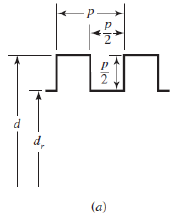

d =  25 %* u.mm;                % Skaft diameter (major diameter)

d = 25

p = 5 %* u.mm;                % Pitch (afstand top til top)

p = 5

G_d = p/2              % gevinddybde

G_d = 2.5000

G_w = p/2              % gevindbrede

G_w = 2.5000

d_r = d - p            % rod diameter - kvadratisk

d_r = 20

d_m = d - p/2      % middeldiameter

d_m = 22.5000

n = 1

n = 1

l = p * n              % Lead(flytning) 

l = 5

d =  25 %* u.mm;                % Skaft diameter (major diameter)

d =     25


p = 5 %* u.mm;                % Pitch (afstand top til top)

p =      5


G_d = p/2              % gevinddybde

G_d =           2.5


G_w = p/2              % gevindbrede

G_w =           2.5


d_r = d - p            % rod diameter - kvadratisk

d_r =     20


d_m = d - p/2      % middeldiameter

d_m =          22.5


d_c = 45; %Krave diameteren (for krave betydning se figur 8-7)) [mm]
n = 1;

n =      1


l = p * n              % Lead(flytning) 

l =      5


F = 5000; % * u.N        % Kraften på screw
f = 0.09;               % Friktionskoefficient for gevind
f_c = 0.06;             %Friktionskoefficient for krave (stykke der holde pladen fra gevindet, se figur 8-7)



T_R = F * d_m / 2 * ((l + pi * f * d_m) / ...
    (pi * d_m - f * l)) %Power ind med friktion  %ligning 8-1

T_R =        9099.3



T_L = F * d_m / 2 * ((pi * f * d_m - l) / ...
    (pi * d_m + f * l)) % ligning 8-1

T_L =        1076.8



T_O = F*l/(2*pi) %Power ud uden friktion %ligning g

T_O =        3978.9




%spindel med krave moment (se figur 8-7 for krave betydning)
T_c = F * f_c * d_c / 2 % ligning 8-6

T_c =         6750



T_R_tot = T_R + T_c

T_R_tot =         15849


T_L_tot = T_L + T_c

T_L_tot =        7826.8



% Virkningsgrad løft
e = T_O / T_R_tot % = F*l/(2*pi*T_R) % ligning 8-4

e =       0.25104



% Virkningsgrad sænkning
e = T_O / T_L_tot % = F*l/(2*pi*T_R) % ligning 8-4

e =       0.50837


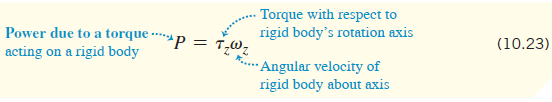

d =  40 * u.mm;                % Skaft diameter (major diameter)
p = 6 * u.mm; %* u.mm;                % Pitch (afstand top til top)
G_d = p/2;              % gevinddybde
G_w = p/2;              % gevindbrede
d_r = d - p;            % rod diameter - kvadratisk
d_m = d - p/2      % middeldiameter

$$d\_m = 37\,\mathrm{mm}$$

d_c = 45; %Krave diameteren (for krave betydning se figur 8-7)) [mm]
n = 2;
l = p * n              % Lead(flytning) 

$$l = 12\,\mathrm{mm}$$


v = 48 * u.mm / u.s;
F = 10000 * u.N;
f = 0.10;
f_c = 0.15;
d_c = 60 * u.mm;

% Vinkelhastighed: Læg mærke til af v/l giver omdr/sek. Der skal derfor ganges med 2*pi
omega = v / l * 2 * pi;
omega_ = vpa(omega ,4)

$$omega\_ = 25.13\,\frac{1}{s}$$



% moment
T_R = F * d_m / 2 * ((l + pi * f * d_m) / ...
    (pi * d_m - f * l)); %ligning 8-1
T_R_ = vpa(T_R,4)

$$T\_R\_ = 37990.0\,N\,\mathrm{mm}$$


% %moment
% T_L = F * d_m / 2 * ((pi * f * d_m - l) / ...
%     (pi * d_m + f * l)) % ligning 8-1

%spindel med krave moment (se figur 8-7 for krave betydning)
T_c = F * f_c * d_c / 2; % ligning 8-6
T_c_ = vpa(T_c,4)

$$T\_c\_ = 45000.0\,N\,\mathrm{mm}$$


%Bidraget fra kraven regnes med
T_R_tot = T_R + T_c; % Total hæve
% T_L_tot = T_L + T_c % Total sænke
T_R_tot_ = vpa(T_R_tot,4)

$$T\_R\_tot\_ = 82990.0\,N\,\mathrm{mm}$$


Power = T_R_tot * omega;
Power_ = unitConvert(vpa(Power,4), u.J)

$$Power\_ = 2085.7861387786865234375\,\frac{J}{s}$$